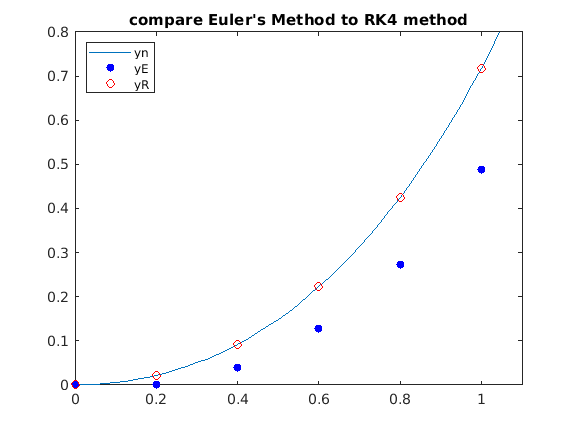

clear
%solution of y
syms y(x)
deq=diff(y,x)==f(x,y); %y'=y+x
cond=y(0)==0; %y(0)=0
ySol(x)=dsolve(deq,cond);

%given-values
n=(0:5)';
h=0.2;
%x-values
x=(h*n(1):h:h*n(end))';
%y-values
yn=double(ySol(x)); % actual values

%Euler's Method
for m=1:length(n)
    if m==1
        yE(m)=0;
    else
        yE(m)=yE(m-1)+h*(yE(m-1)+x(m-1));
    end
end
yE=yE'; %approximate values with Euler's Method

%RK4 Method
for m=1:length(n)
    if m==1
        yR(m)=0;
        k1(m)=f(x(m),yR(m));
        k2(m)=f(x(m)+h/2,yR(m)+h/2*k1(m));
        k3(m)=f(x(m)+h/2,yR(m)+h/2*k2(m));
        k4(m)=f(x(m)+h,yR(m)+h*k3(m));
        ks=k1+2*k2+2*k3+k4;
    else
        yR(m)=yR(m-1)+h/6*ks(m-1);
        k1(m)=f(x(m),yR(m));
        k2(m)=f(x(m)+h/2,yR(m)+h/2*k1(m));
        k3(m)=f(x(m)+h/2,yR(m)+h/2*k2(m));
        k4(m)=f(x(m)+h,yR(m)+h*k3(m));
        ks=k1+2*k2+2*k3+k4;
    end
end
yR=yR'; % approximate values with Runge-Kutta Method

%errors=difference between actual values and approximate values
errorE=yn-yE; %error with Euler's Method
errorR=yn-yR; %error with Runge-Kutta Method

%plot
fplot(ySol)
hold on
plot(x,yE,'b.','Markersize',20)
hold on
plot(x,yR,'ro')
xlim([0 1.1])
ylim([0 0.8])
title("compare Euler's Method to RK4 method")
legend({'yn','yE','yR'},'Location',"northwest")


%table
cmptable=table(n,x,yE,yR,yn,errorE,errorR)

cmptable = 6×7 table
    n     x       yE          yR          yn        errorE       errorR  
    _    ___    _______    ________    ________    ________    __________

    0      0          0           0           0           0             0
    1    0.2          0      0.0214    0.021403    0.021403    2.7582e-06
    2    0.4       0.04    0.091818    0.091825    0.051825    6.7376e-06
    3    0.6      0.128     0.22211     0.22212    0.094119    1.2344e-05
    4    0.8     0.2736     0.42552     0.42554     0.15194    2.0103e-05
    5      1    0.48832     0.71825     0.71828     0.22996    3.0692e-05


function [z]=f(x,y)
z=y+x;
end